# Example - AC Stark Map

clear all
addpath("Molecules\");addpath("Atoms\");addpath("functions\");
C = Constants;
set(groot,'defaultAxesXGrid','on')
set(groot,'defaultAxesYGrid','on')
set(groot,'defaultAxesBox','on')
set(groot,'defaultAxesLineWidth',0.5)

## Define Fields

maxN = 2;

B.value = 181.5;
B.dir = [0,0,1];
B.scaling = 1e-4; %put B.value in Gauss, not Tesla

E.value = 0; %V/m
E.dir = [0,0,1];
E.scaling = 1e2;%put E.value in V/cm, not V/m

I.value = linspace(0,10,51);
I.dir = [0,1,0];
theta=pi/2;
I.pol = [sin(theta),0,cos(theta)];
I.scaling = 1e7;%put I.value in kW/cm^2, not W/m^2

Fields.B = B;
Fields.E = E;
Fields.I = I;

## Define Hamiltonian

Mol = RbCs(87,133);
% Mol.a0=0; %To reproduce plot figure 6 from Diatomic-py, set Mol.a0 to
% zero and remove the scalar offset when plotting
Ham = Hamiltonian(Molecule = Mol, Fields=Fields, maxN=maxN);
H0 = Ham.hyperfine.total + E.value*E.scaling*Ham.dc_stark + B.value*B.scaling*Ham.zeeman;
Base = Ham.Basis;
nStates = Base.NStates;
st = Base.getStates("all");

## Diagonalise for varying intensity

F = I;
x = F.value;
energyMap = nan(length(x),nStates);
statesMap = nan(length(x),nStates,nStates);
disp("Diagonalising - ")

Diagonalising - 


for k = 1:length(x)
    if mod(k,10)==1; fprintf("%d - ",k); end
    H = H0 + x(k)*F.scaling*Ham.ac_stark;
    [V,D] = eig(full(H/C.h),'vector'); %no need to use sparse matrices for matrices smaller than 1000x1000. Divide by Plancks constant to get energy in Hz
    [d,sortIdx] = sort(real(D));
    energyMap(k,:)=d;        
    statesMap(k,:,:) = V(:,sortIdx);
end

1 - 11 - 21 - 31 - 41 - 51 - 

disp("Finished")

Finished


## Plotting

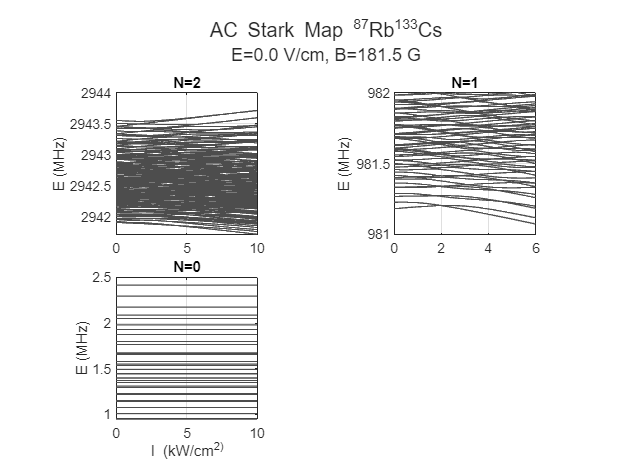

scalarACoffset = (Mol.a0/(2*C.e0*C.c))*x*F.scaling / C.h;
% scalarACoffset = 0;
GSEnergy = (min(energyMap,[],'all')-scalarACoffset)'*1e-6;

N = Base.getStates("N");
figure(12); clf;
t = tiledlayout("flow",TileSpacing="tight");

nexttile(t); %N=2 manifold
plot(x,energyMap(:,N==2)*1e-6-GSEnergy, color=[1,1,1]*0.3);
ylabel(sprintf("E (MHz)"))
% xticklabels([])
% ylim([1,4]+5880)
xlim([min(x),max(x)])
axis square
title("N=2")

nexttile(t); %N=1 manifold
plot(x,energyMap(:,N==1)*1e-6-GSEnergy, color=[1,1,1]*0.3);
ylabel(sprintf("E (MHz)"))
% xticklabels([])
ylim([0,1]+981) %87Rb133CS
% ylim([2227.5,2228.5]) %40K87Rb
% xlim([min(x),max(x)])
xlim([0,6])
axis square
title("N=1")
% 
nexttile(t); %N=0 manifold
plot(x,energyMap(:,N==0)*1e-6-GSEnergy, color=[1,1,1]*0.3); hold on;
ylabel(sprintf("E (MHz)"))
% ylim([-3,1])
xlim([min(x),max(x)])
axis square
title("N=0")

xlabel("I (kW/cm^2)")
title(t,sprintf("AC Stark Map %s",Mol.name))
subtitle(t, sprintf("E=%.1f V/cm, B=%.1f G", Fields.E.value,Fields.B.value))

## Diagonalise for varying polarisation